# **Deep Learning for Signal Data**

This exercise shows how you can build a model using transfer learning techniques to classify signal data.  We will use a Wavelet Transform to generate a time-frequency representation of a signal.  

The convolutional neural network will be trained to detect whether an echocardiogram (ECG) signal comes from a heart with: 

- *Normal Sinus Rhythm (NSR)*

- *Arrythmia (ARR) *

- *Congestive Heart Failure (CHF)*

# **Explore the Signals**

## Load Signals

The data are 162 sample signals, sampled at a frequency (Fs) of 128Hz.

load('ECGData.mat')

# **Generate Wavelet Time-Frequency Representations**

## Visualize one time-frequency image

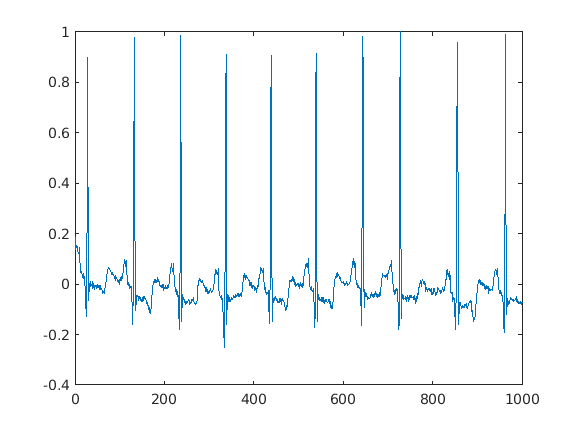

figure
plot(Arrythmia_Sample)

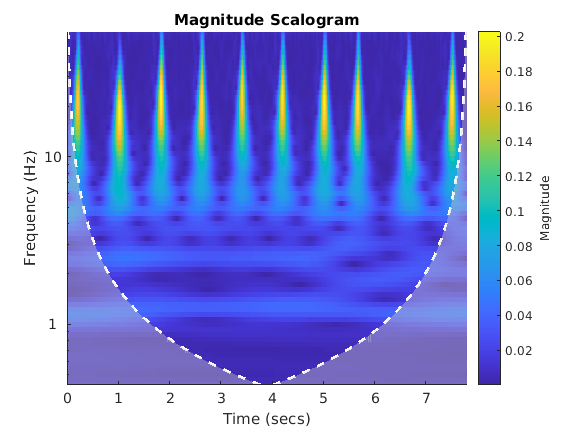

figure
cwt(Arrythmia_Sample,Fs)

**Generate Time-Frequency Visualizations for all Signals**

Open the [`PrepareSignalData.mlx`](matlab:edit('PrepareSignalData.mlx');) file.  This script applies the continuous wavelet transform to all the siganls and saves the images in 'data' folder. step has already been done, so you **do not run the script.** 

% edit PrepareSinalData.mlx

## Split the Time-Frequency Representation Images into Training and Test Sets

The `imageDatastore` points at directories of labeled data and will automatically create training and testing sets.  Image datastores can be directly passed into the neural network training function.  The *ReadFcn* makes sure the image size agrees with the first input layer size requirement.

readFcn = @(imagefilename)imresize(imread(imagefilename), [227 227]);

filepath = "data"; 
allImages = imageDatastore(filepath, 'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames', 'ReadFcn', readFcn);
[trainingImages, testImages] = splitEachLabel(allImages, 0.8, 'randomize');

# **Train a Pre-Trained Network**

## **Initialize the Network **

We'll load in the pretrained `alexnet` network.  This can be downloaded from the add-ons manager.  In order to retrain just the last few layers, we will replace them with a new `fullyConnectedLayer` and a new `classificationLayer`.

alex = alexnet;
layers = alex.Layers;

layers(23) = fullyConnectedLayer(3);
layers(24) = softmaxLayer(); 
layers(25) = classificationLayer("Classes", {'ARR', 'CHF', 'NSR'});


Alternatively use the Deep Network Designer App to replace the layers 

deepNetworkDesigner

## **Train the Network**

Retrain the network. Use the following training options and save them to variable "opts"

- `InitialLearnRate 0.0001`

- `MaxEpochs        12 `

- `MiniBatchSize    10 `

`Hint : ``doc trainingOptions `

opts = trainingOptions('sgdm', 'InitialLearnRate', 0.0001, ...
        'MaxEpochs', 12, 'MiniBatchSize', 10, ...
        'Plots', 'training-progress', 'ExecutionEnvironment',"parallel");

Now train the network and save it to variable "ECGNet"

`Hint : ``doc trainNetwork `

ECGNet = trainNetwork(trainingImages, layers, opts);

# **Evaluate the Trained Model**

Use the trained model on the test image set and show the confusion matrix.

predictedLabels = classify(ECGNet, testImages);
accuracy = sum(predictedLabels == testImages.Labels) / numel(predictedLabels);
[confmat, order] = confusionmat(testImages.Labels, predictedLabels);
figure
heatmap(order, order, confmat);
title("Confusion Matrix, Accuracy " + accuracy*100 + "%")